# Set Plotting Style

set(groot, 'defaultAxesFontSize',15);

# Butterworth filter design

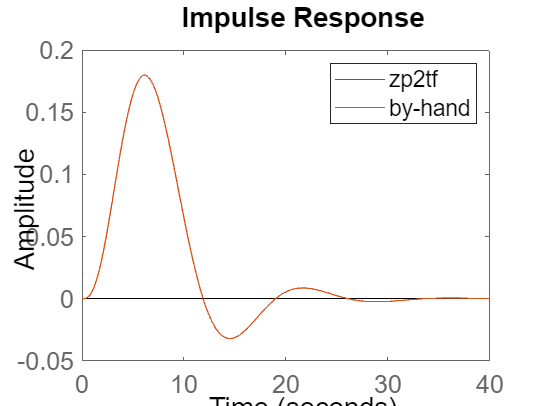

N = 4;
w_c = 0.3*pi;
T_d = 2;

Om_c = w_c/T_d;
poles = Om_c*exp(1i*pi/(2*N)*(2*[0 1 2 3]+N+1));
zeros = [];
[num, den] = zp2tf(zeros, poles, Om_c^N);
num2 = Om_c^N;
den2 = poly(poles);
sys = tf(num, den);
sys2 = tf(abs(num2), abs(den2));

figure;
impulse(sys);
hold on;
impulse(sys2);
hold off;
legend(["zp2tf", "by-hand"]);

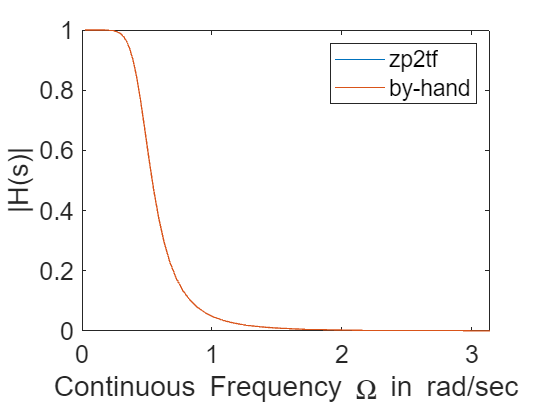


figure;
[H_s, w] = freqs(num, den, 1e2);
[H_s2, w2] = freqs(num2, den2, 1e2);
plot(w, abs(H_s));
hold on;
plot(w2, abs(H_s2));
hold off;
legend(["zp2tf", "by-hand"]);
xlim([0, pi]);
ylabel("|H(s)|");
xlabel("Continuous Frequency \Omega in rad/sec");

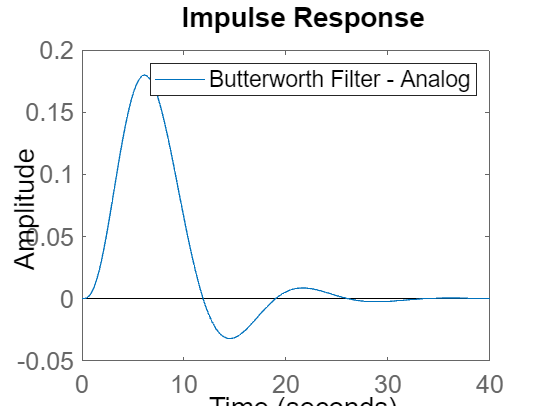


figure;
impulse(sys);
legend(["Butterworth Filter - Analog"]);

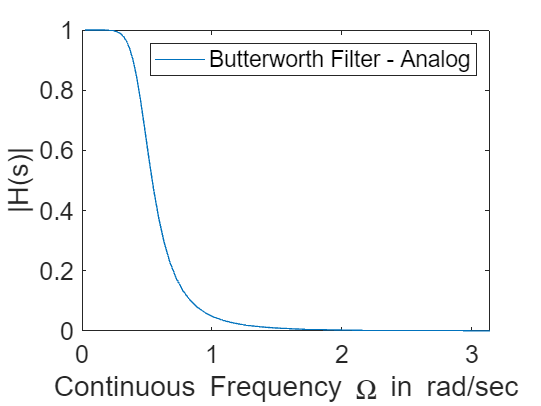


figure;
plot(w, abs(H_s));
xlim([0, pi]);
ylabel("|H(s)|");
xlabel("Continuous Frequency \Omega in rad/sec");
legend(["Butterworth Filter - Analog"]);

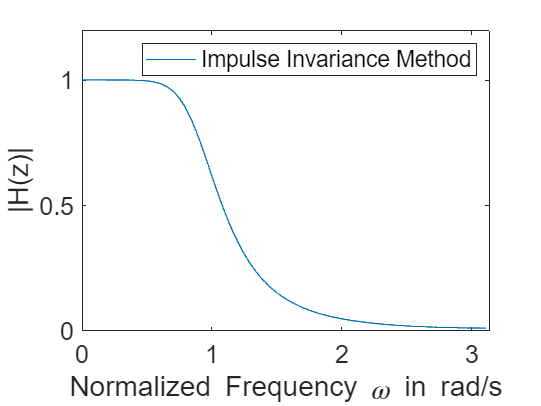


% cont -> discrete:
[b_z, a_z] = impinvar(num, den, 1/T_d);
[H_z, w_z] = freqz(b_z, a_z, 1e2);
plot(w_z, abs(H_z));
ylabel("|H(z)|");
xlabel("Normalized Frequency \omega in rad/s");
xlim([0, pi]);
legend(["Impulse Invariance Method"]);

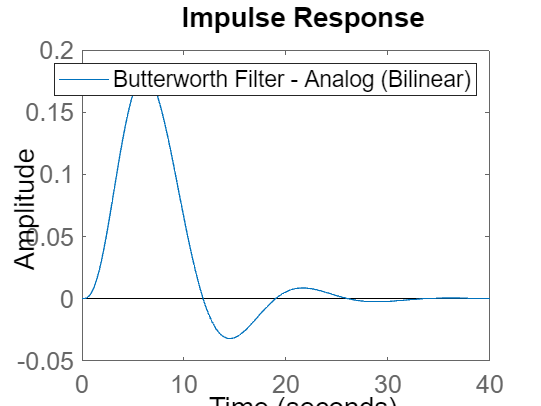

% Bilinear Transformation
Om_c_bil = 2/T_d * tan(w_c/2);
poles_bil = Om_c_bil*exp(1i*pi/(2*N)*(2*[0 1 2 3]+N+1));
zeros_bil = [];
[num, den] = zp2tf(zeros_bil, poles_bil, Om_c_bil^N);
sys_bil = tf(num, den);
[numd, dend] = bilinear(poly(zeros_bil), poly(poles_bil)/Om_c_bil^N, 1/T_d);
%[zd, pd, kd] = bilinear(zeros, poles, Om_c^N, 1/T_d);

figure;
impulse(sys);
legend(["Butterworth Filter - Analog (Bilinear)"]);

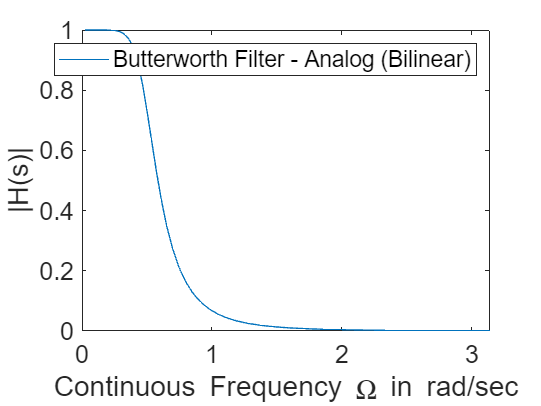


[H_s_bil, w_bil] = freqs(num, den, 1e2);
figure;
plot(w_bil, abs(H_s_bil));
xlim([0, pi]);
ylabel("|H(s)|");
xlabel("Continuous Frequency \Omega in rad/sec");
legend(["Butterworth Filter - Analog (Bilinear)"]);

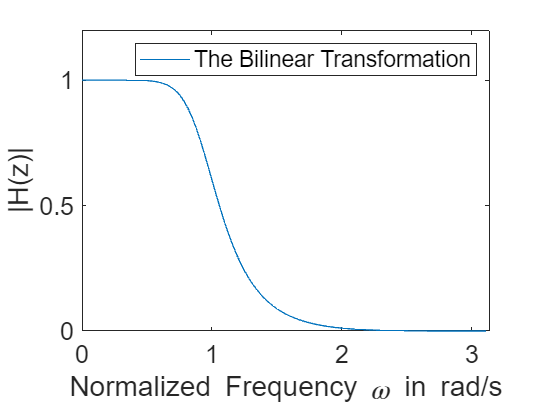



[H_z_bilinear w_z_bilinear] = freqz(numd, dend, 1e2);
plot(w_z_bilinear, abs(H_z_bilinear));
ylabel("|H(z)|");
xlabel("Normalized Frequency \omega in rad/s");
xlim([0, pi]);
legend(["The Bilinear Transformation"]);

## Comparison

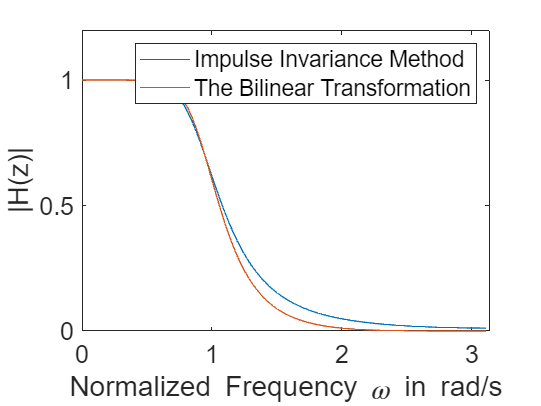

figure;
%plot(abs(H_s));
%hold on;
plot(w_z, abs(H_z));
hold on;
plot(w_z_bilinear, abs(H_z_bilinear));
hold off;
ylabel("|H(z)|");
xlabel("Normalized Frequency \omega in rad/s");
xlim([0, pi]);
legend(["Impulse Invariance Method", "The Bilinear Transformation"]);

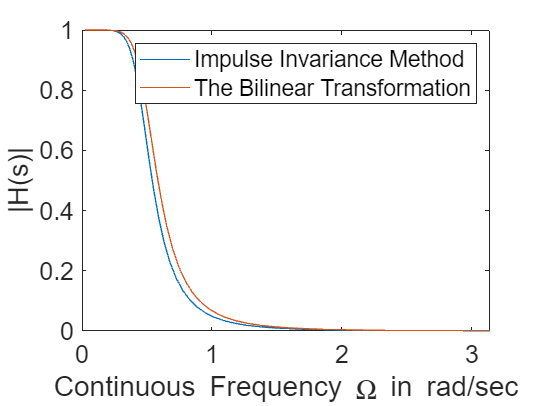


figure;
plot(w, abs(H_s));
hold on;
plot(w_bil, abs(H_s_bil));
hold off;
xlim([0, pi]);
ylabel("|H(s)|");
xlabel("Continuous Frequency \Omega in rad/sec");
legend(["Impulse Invariance Method", "The Bilinear Transformation"]);

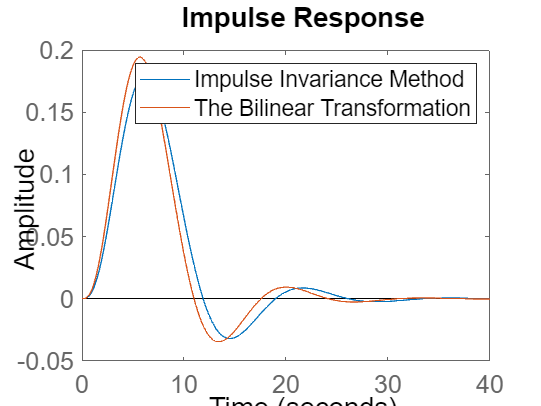


figure;
impulse(sys);
hold on;
impulse(sys_bil);
hold off;
legend(["Impulse Invariance Method", "The Bilinear Transformation"]);